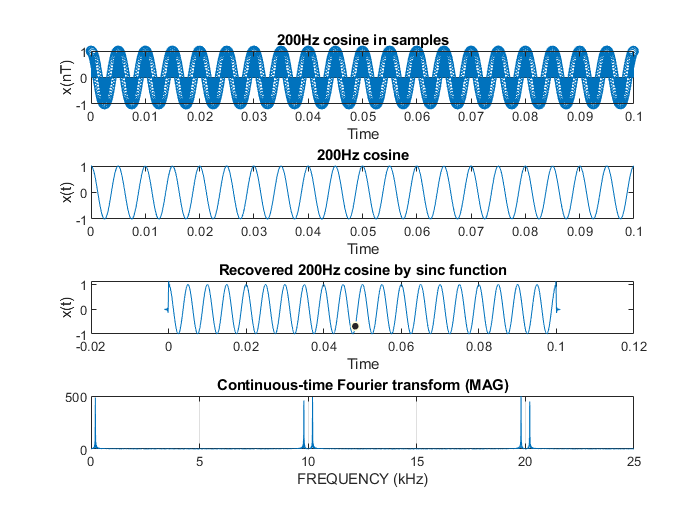

% If we increase the sampling frequency for sinc?
% Here sampling sinc at 100kHz (The cheating frequency for sinc)
clear all;
close all;
clc;

M = zeros(10201, 1000);
sinc_result= zeros(10201, 1000);
for i = 1:1000
    %     Use 100kHz to 'cheat' in the sinc function.
    x = (-10 + i - 1) * 1e-4:1e-5:(10 + i - 1) * 1e-4;
    M(1+(i-1)*10:1+(i-1)*10+200, i) = x;
    sinc_result([1+(i-1)*10:1+(i-1)*10+200], i) = sinc( (M(1+(i-1)*10:1+(i-1)*10+200, i)- (i-1) * 1e-4) / 1e-4);
end

N = 1000; 
fs = 10000; % 10kHz sampling frequency
T = 1/fs; % sample period
T_for_cheating = 1/10 * T; % Cheating frequency for cos is 100kHz.
f = 200; % signal frequency in Hz
n = 0:N-1; % discrete time vector
% Since we change the cheating frequency for the cos, we also have to
% change the number of samples to make sure that we plot the cos for 0.1
% second.
n_for_cheat = 0:10000;
x = cos(2*pi*f*n*T);
x_for_cheat = cos(2*pi*f*n_for_cheat*T_for_cheating); %signal definition, 'cheat' here by 10 times the sampling frequency.
%plot the signal against time
subplot(4,1,1);
y = stem(n*T,x);
sample_data = y.YData;
title('200Hz cosine in samples');
xlabel('Time');
ylabel('x(nT)');

subplot(4,1,2);
plot(n_for_cheat / 1e5, x_for_cheat);
title('200Hz cosine');
xlabel('Time');
ylabel('x(t)');

signal_recover_times_samples = sample_data .* sinc_result;
signal_recover_final = sum(signal_recover_times_samples, 2);
t = -10 * T:1e-5:0.1 + 10 * T;
subplot(4,1,3);
plot(t, signal_recover_final);
title('Recovered 200Hz cosine by sinc function');
xlabel('Time');
ylabel('x(t)');

% At the beginning and end of the recovering curve, the recovering result
% was not satisfactory, I think this was due to the reason that both at the
% beginning and end of the curve, there was not enough sinc function value
% to help build the recover signal (because we tuncated the sinc function
% within +-10T and think about the mathematic representation of the
% recovered signal, which is the summation of the sinc times corresponding
% sample data value, there was not enough sinc function value at the
% beginning of the recovered signal (actually only one sinc function value
% at the first few recovered signal points), the recovered signal value was
% exactly the value of sinc function at the beginning and end.)

subplot(4,1,4);
% fft_for_spike = fft(sample_data);
spike_train = zeros(10000,1)';
index = 1;
for i = 1:10000
    if mod(i,10)==1
        spike_train(i) = sample_data(index);
        index = index + 1;
    end
end
fmagplot(spike_train, 1e-5);

hold off;

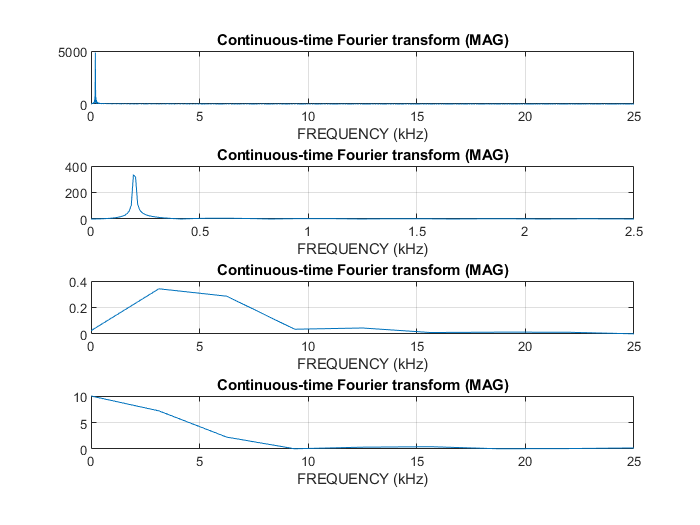

figure

subplot(4,1,1);
fmagplot(x_for_cheat,1e-5);
subplot(4,1,2);
fmagplot(sample_data, 1e-4);
subplot(4,1,3);
fmagplot(sinc_result(1:21,1), 1e-5);
subplot(4,1,4);
x = -1e-4:1e-5:1e-4;
linear_result = (1e-4 - abs(x)) / 1e-4;
fmagplot(linear_result, 1e-5);

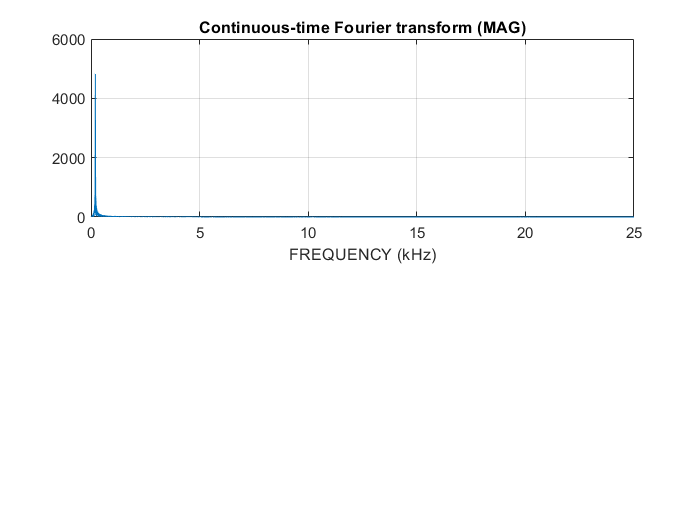


figure
% Frequency plot for recovered signal based on sinc.
subplot(2,1,1);
fmagplot(signal_recover_final, 1e-5);